## Strategy Estimation for Las Vegas GP 2023

% Tyres available: C3, C4, C5 - The 3 softest in the Pirelli range.
% Race Duration: 50 laps (305.88km total distance)

% Assumption of tyre pace delta per lap: 0.5s between C5 and C4, and 0.5s
% between C4 and C3. With C5 being the fastest.

% Assumption of degradation per lap: Fuel corrected laptime increase
% linearly as tyre wears (linear tyre deg model assumed due to lack 
% of detailed information on compounds)

% Fuel correction assumption for 110kg of fuel to last 50 laps and 0.035s
% laptime gain per 1kg of fuel burn.

% Initial flying lap pace assumed due to lack of race historical data. 

Calculating Fuel Correction Factor

fuelQuantity = 110;  %kg
totalLapNumber = 50; %laps
lapNumber = 1:50;
timePerKg = 0.035;   %seconds

fuelConsumption = fuelQuantity/totalLapNumber;   %kg/lap

fuelCorrectionFactor = fuelConsumption .* timePerKg; %seconds/lap

fuelLapCorrections = fuelCorrectionFactor .* (lapNumber-1);

Defining Tyre Wear Factors

c5Wear = 0.14; %s/lap
c4Wear = 0.12;  %s/lap
c3Wear = 0.09; %s/lap

tyreAge = 1:50; %laps

Calculating Tyre Degradation Laptime Impact

c5InitialLaptime = 95;   %seconds
c4InitialLaptime = 95.5; %seconds
c3InitialLaptime = 96;   %seconds

c5TyreDegLaptime = c5InitialLaptime + c5Wear .* (tyreAge-1);
c4TyreDegLaptime = c4InitialLaptime + c4Wear .* (tyreAge-1);
c3TyreDegLaptime = c3InitialLaptime + c3Wear .* (tyreAge-1);

Calculating Tyre and Fuel Effected Laptimes

c5Laptime = c5InitialLaptime + (c5Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);

c5Laptime =    95.0000   95.0630   95.1260   95.1890   95.2520   95.3150   95.3780   95.4410   95.5040   95.5670   95.6300   95.6930   95.7560   95.8190   95.8820   95.9450   96.0080   96.0710   96.1340   96.1970   96.2600   96.3230   96.3860   96.4490   96.5120   96.5750   96.6380   96.7010   96.7640   96.8270   96.8900   96.9530   97.0160   97.0790   97.1420   97.2050   97.2680   97.3310   97.3940   97.4570   97.5200   97.5830   97.6460   97.7090   97.7720   97.8350   97.8980   97.9610   98.0240   98.0870


c4Laptime = c4InitialLaptime + (c4Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);

c4Laptime =    95.5000   95.5430   95.5860   95.6290   95.6720   95.7150   95.7580   95.8010   95.8440   95.8870   95.9300   95.9730   96.0160   96.0590   96.1020   96.1450   96.1880   96.2310   96.2740   96.3170   96.3600   96.4030   96.4460   96.4890   96.5320   96.5750   96.6180   96.6610   96.7040   96.7470   96.7900   96.8330   96.8760   96.9190   96.9620   97.0050   97.0480   97.0910   97.1340   97.1770   97.2200   97.2630   97.3060   97.3490   97.3920   97.4350   97.4780   97.5210   97.5640   97.6070


c3Laptime = c3InitialLaptime + (c3Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);

c3Laptime =    96.0000   96.0130   96.0260   96.0390   96.0520   96.0650   96.0780   96.0910   96.1040   96.1170   96.1300   96.1430   96.1560   96.1690   96.1820   96.1950   96.2080   96.2210   96.2340   96.2470   96.2600   96.2730   96.2860   96.2990   96.3120   96.3250   96.3380   96.3510   96.3640   96.3770   96.3900   96.4030   96.4160   96.4290   96.4420   96.4550   96.4680   96.4810   96.4940   96.5070   96.5200   96.5330   96.5460   96.5590   96.5720   96.5850   96.5980   96.6110   96.6240   96.6370


Defining Average Pit Time Loss

pitTime = 20;  %seconds

Predict Race Time for C4 to C3 (1 stop) Strategy. Consider a pit stop on lap 20.

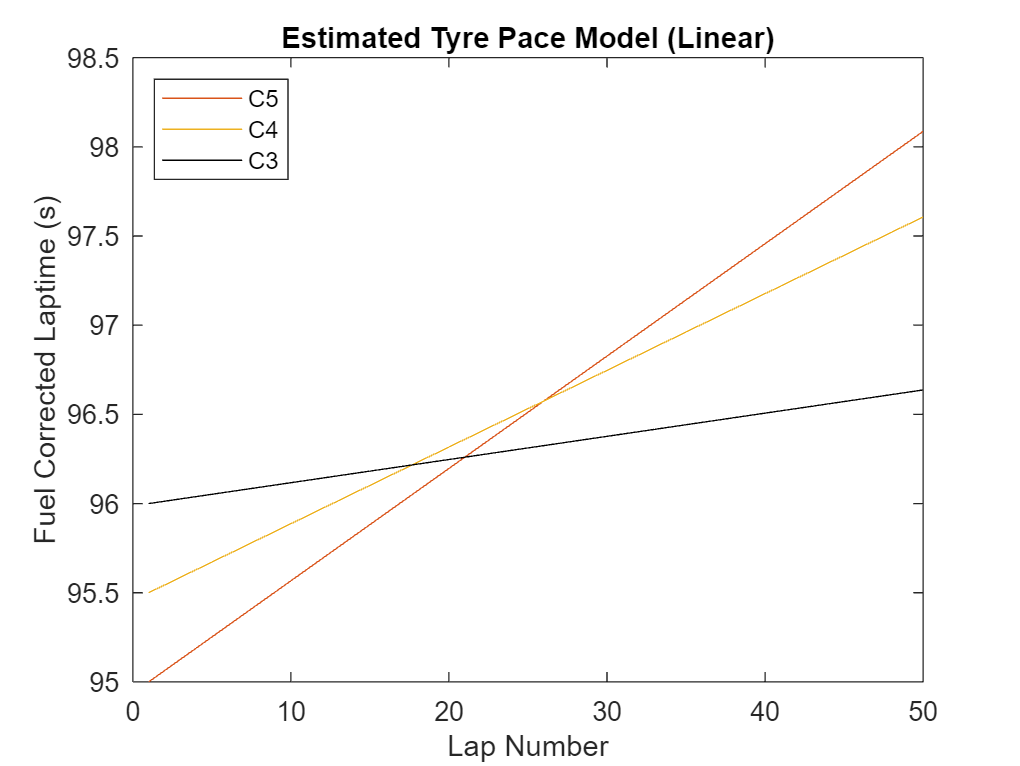

plot(lapNumber,c5Laptime,"Color","#D95319")
hold on
plot(lapNumber,c4Laptime,"Color","#EDB120")
plot(lapNumber,c3Laptime,"Color","#000000")
xlabel("Lap Number")
ylabel("Fuel Corrected Laptime (s)")
title("Estimated Tyre Pace Model (Linear)")
legend(["C5" "C4" "C3"],"Location","northwest")